clear all
close all

Leggo file audio

[data,Fs]=audioread('Audio/KDE_Startup.wav');

data=data(:,1)';

Dati

V = max(abs(data))

V = 1

nbit=6

nbit = 6

M=2^nbit

M = 64

DeltaV=2*V/M

DeltaV = 0.0313

pe=1e-5

pe = 1.0000e-05

Tc = 1/Fs

Tc = 4.5351e-05

B = 1/(2*Tc)

B = 11025

mu = 255

mu = 255


data_ = data*(1/V);
data_scalato = data_;

Companding compress

data_ = compand(data_, mu, V, 'mu/compressor');

Partizzazione uniforme

partition=[-V+DeltaV:DeltaV:V-DeltaV];
codebook=[-V+DeltaV/2:DeltaV:V-DeltaV/2];
[index,quants]=quantiz(data_,partition,codebook);

word=de2bi(index,nbit);
word_out=bsc(word,pe);

Output ed errore

index_out=bi2de(word_out);
sig_out=codebook(index_out+1);

Copanding expand

sig_out = compand(sig_out, mu, V, 'mu/expander');

Error signal

err=sig_out-data_scalato;

Grafici

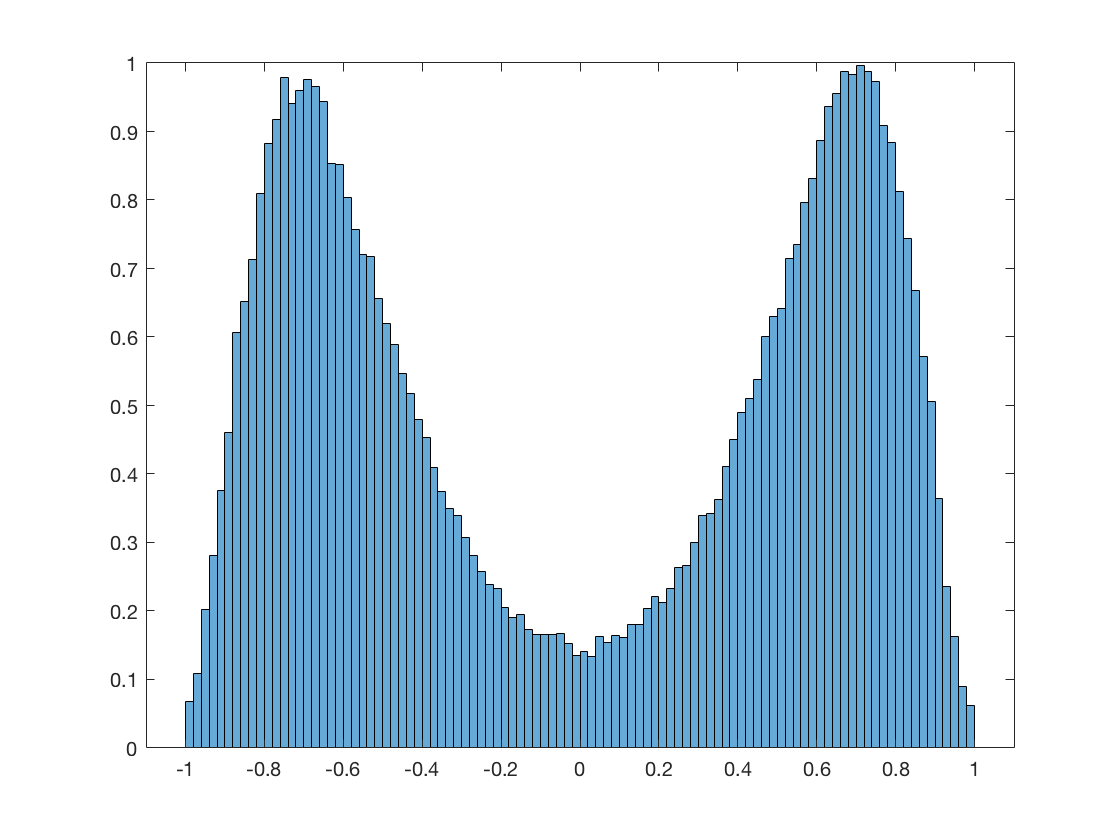

figure(1)
histogram(data_, 100, 'Normalization', 'pdf')

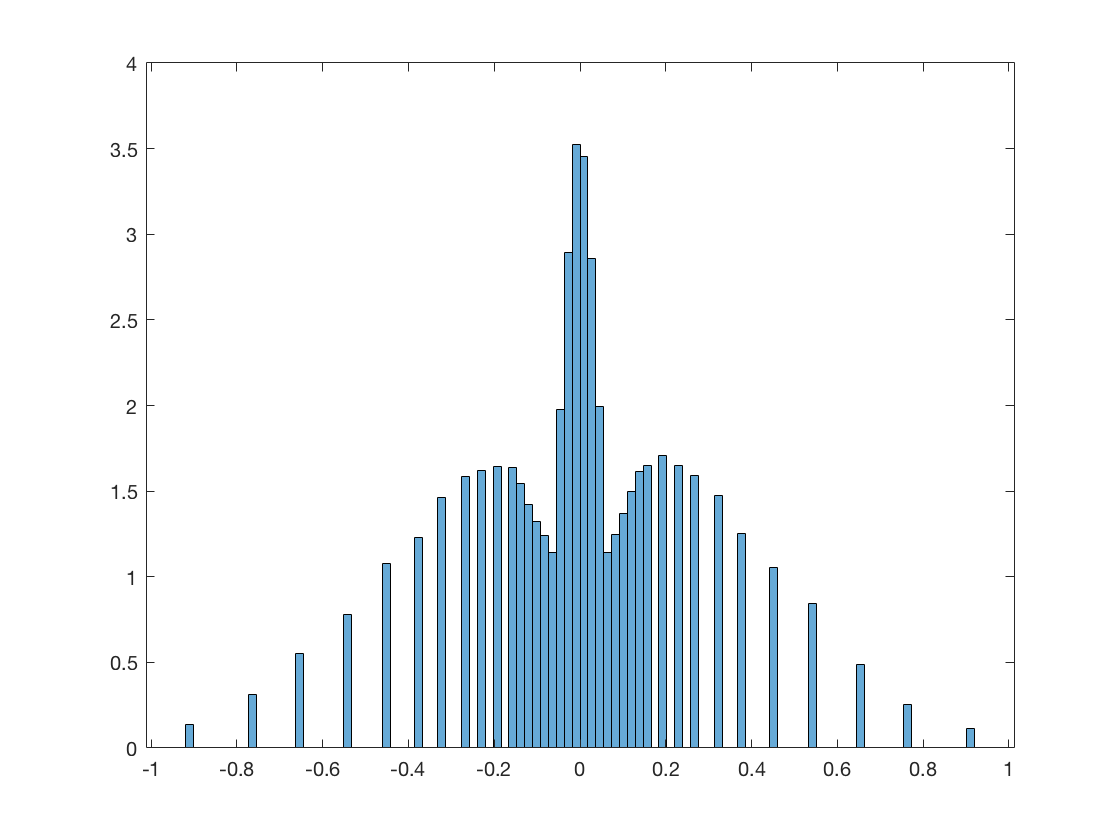


figure(2)
histogram(sig_out, 100, 'Normalization', 'pdf')

Calcolo rapporto S/N teorico e pratico

N=var(err)

N = 1.6127e-04

S=var(data_scalato)

S = 0.0610


10*log10(S/N)

ans = 25.7810


10*log10((3*M^2)/(V^2)*S)

ans = 28.7513


10*log10(M^2)

ans = 36.1236